clear;clc;
G1=zpk([],[-1],1);
G2=zpk([0],[],1);
G3=zpk([],[0],1);
GZ1=feedback(G1,1)

GZ1 =
 
    1
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.



GZ2=feedback(G1*G2,1)

GZ2 =
 
   0.5 s
  -------
  (s+0.5)
 
Continuous-time zero/pole/gain model.



GZ3=feedback(G1*G3,1)

GZ3 =
 
        1
  -------------
  (s^2 + s + 1)
 
Continuous-time zero/pole/gain model.



syms s;
gz1=ilaplace(1/(s+2)/s)

$$gz1 = \frac{1}{2}-\frac{{\mathrm{e}}^{-2\,t}}{2}$$

$$gz1 = \delta^{\prime \prime }(t)$$

gz3=ilaplace(5/(s^2+s+5)/s)

$$gz3 = 1-{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{19}\,t}{2}\right)+\frac{\sqrt{19}\,\sin\left(\frac{\sqrt{19}\,t}{2}\right)}{19}\right)$$

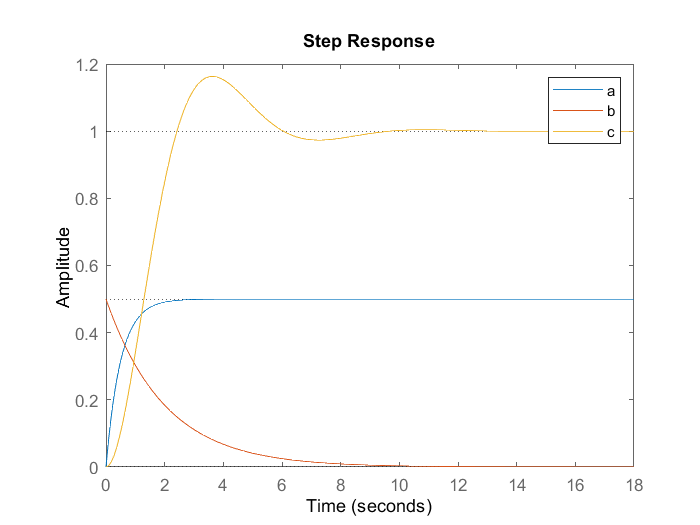

step(GZ1)
hold on;
step(GZ2)
step(GZ3)
legend('a','b','c')
hold off;